%Om anvendelse med periodiske signaler generelt
%I en kompleks Fourier-række er c_n bærer af oplysninger om frekvensspektret
%Som eksempel defineres nu et periodisk firkantsignal
clear
close all
clc

fs=10000; %Samplingfrekvens på 10000 Hz
Ts=1/fs; %Samplinginterval på 0,1 ms
T1=100*Ts %Periodetid på 10 ms, altså 100 samples per periode

T1 = 0.0100

f1=1/T1; %Grundfrekvens på 100 Hz
N=1000; %Antal samples
n=0:N-1;
fs/N %Frekvensopløsning til FFT-beregning

ans = 10

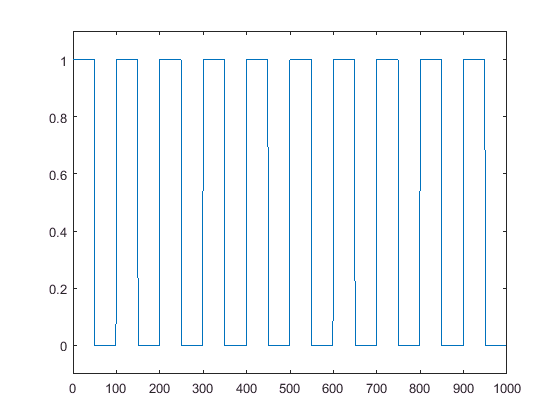

x_periode = [ones(1,50), zeros(1,50)];
x=[];
for i=1:10
    x=[x, x_periode];
end
plot(n,x)
axis([0 1000 -0.1 1.1]) %Zoomer

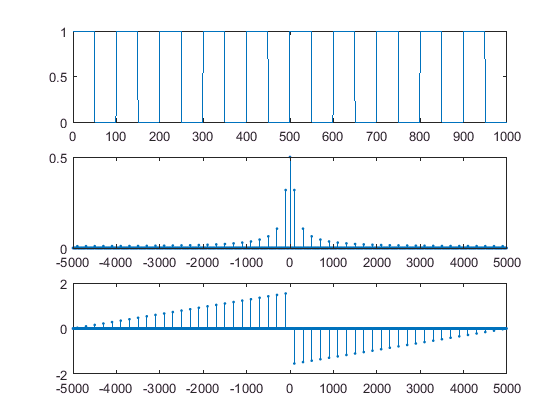

%Plottet viser et korrekt firkantsignal

%Beregning af frekvensspektret
plot_x_og_X(x,N,fs)

%Plottet viser korrekte amplituder og faser